clc
clear

RAS_data = readtable("Test_Sirius_Normal_Flight.CSV");

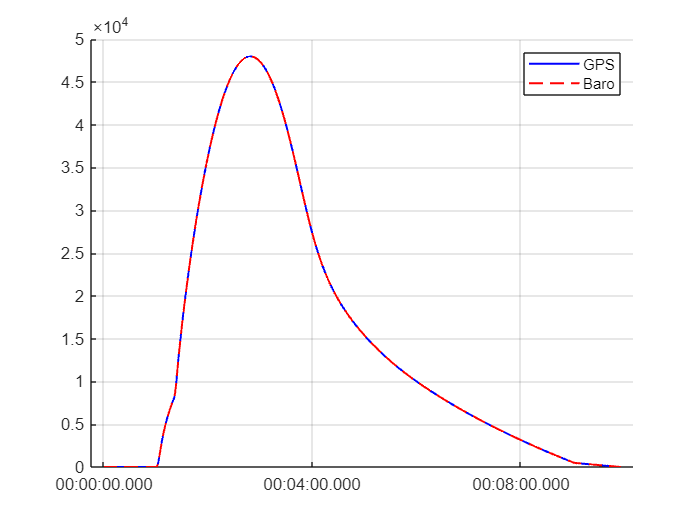

heading_angle = 45; % deg
idle_time = 0:0.1:10; % 10 s idle time

alt = vertcat(repmat(RAS_data.Altitude_ft_(1,1)*0.3048, length(idle_time), 1), RAS_data.Altitude_ft_*0.3048);
dist = vertcat(repmat(RAS_data.Distance_ft_(1,1)*0.3048, length(idle_time), 1), RAS_data.Distance_ft_*0.3048);
x = vertcat(repmat(dist(1,1).*cosd(heading_angle), length(idle_time), 1), dist.*cosd(heading_angle));
y = vertcat(repmat(dist(1,1).*sind(heading_angle), length(idle_time), 1), dist.*sind(heading_angle));

lat0 = 35.3472;
lon0 = 117.8082;
h0 = 2079*0.3048;

for i=1:length(RAS_data.Altitude_ft_)+length(idle_time)
    [gps_long(i), gps_lat(i), gps_alt(i)] = ned2geodetic(x(i), y(i), alt(i), lat0, lon0, h0, wgs84Ellipsoid);
    [T(i), ~, P(i)] = atmosisa(alt(i), extended=true);
end

gps_long = gps_long';
gps_lat = gps_lat';
gps_alt = alt*1000;

gps_v_n = vertcat(zeros(length(idle_time),1), RAS_data.Vel_H_ft_sec_.*cosd(heading_angle)*0.3048*1000);
gps_v_e = vertcat(zeros(length(idle_time),1), RAS_data.Vel_H_ft_sec_.*sind(heading_angle)*0.3048*1000);
gps_v_d = vertcat(zeros(length(idle_time),1), -1*RAS_data.Vel_V_ft_sec_*0.3048*1000);

gps_sat = repmat(17, length(RAS_data.Time_sec_)+length(idle_time), 1);
gps_fix = repmat(3, length(RAS_data.Time_sec_)+length(idle_time), 1);

ax = vertcat(zeros(length(idle_time), 1), RAS_data.Accel_H_ft_sec_2_.*cosd(heading_angle)*0.3048/9.81);
ay = vertcat(zeros(length(idle_time), 1), RAS_data.Accel_H_ft_sec_2_.*sind(heading_angle)*0.3048/9.81);
az = vertcat(-1*ones(length(idle_time), 1), RAS_data.Accel_V_ft_sec_2_*0.3048/9.81);

gx = zeros(length(RAS_data.Time_sec_)+length(idle_time), 1); % check 
gy = zeros(length(RAS_data.Time_sec_)+length(idle_time), 1); % check 
gz = zeros(length(RAS_data.Time_sec_)+length(idle_time), 1); % check

imu_temp = repmat(57.5, length(RAS_data.Time_sec_)+length(idle_time), 1);
baro_alt = gps_alt/1000;
% baro_temp = (T - 273.15)';
baro_temp = repmat(52.0, length(RAS_data.Time_sec_)+length(idle_time), 1);
baro_press = P';

batt_volt = repmat(1679, length(RAS_data.Time_sec_)+length(idle_time), 1);
batt_percent = repmat(65366, length(RAS_data.Time_sec_)+length(idle_time), 1);

telemetry_RAS = table(gps_long, gps_lat, gps_alt, gps_v_n, gps_v_e, gps_v_d, ax, ay, az, gx, gy, gz, baro_alt, baro_press, baro_temp);
time = seconds(vertcat(idle_time', RAS_data.Time_sec_ + 60));
time.Format='hh:mm:ss.SSS';
gps_long=table2timetable(telemetry_RAS(:,1),'RowTimes',time);
gps_lat=table2timetable(telemetry_RAS(:,2),'RowTimes',time);
gps_alt=table2timetable(telemetry_RAS(:,3),'RowTimes',time);
gps_v_n=table2timetable(telemetry_RAS(:,4),'RowTimes',time);
gps_v_e=table2timetable(telemetry_RAS(:,5),'RowTimes',time);
gps_v_d=table2timetable(telemetry_RAS(:,6),'RowTimes',time);

ax=table2timetable(telemetry_RAS(:,7),'RowTimes',time);
ay=table2timetable(telemetry_RAS(:,8),'RowTimes',time);
az=table2timetable(telemetry_RAS(:,9),'RowTimes',time);

gx=table2timetable(telemetry_RAS(:,10),'RowTimes',time);
gy=table2timetable(telemetry_RAS(:,11),'RowTimes',time);
gz=table2timetable(telemetry_RAS(:,12),'RowTimes',time);

baro_alt=table2timetable(telemetry_RAS(:,13),'RowTimes',time);
baro_temp=table2timetable(telemetry_RAS(:,14),'RowTimes',time);
baro_press=table2timetable(telemetry_RAS(:,15),'RowTimes',time);

time_adjust = seconds(0); time_adjust.Format='hh:mm:ss.SSS';

figure
hold on
plot(time,telemetry_RAS.gps_alt./1000,'-b',LineWidth=1.2)
plot(time,telemetry_RAS.baro_alt,'--r',LineWidth=1.2)
% plot(time-time_adjust,telemetry_RAS.pd,'-k',LineWidth=1.2)
grid on 
legend('GPS', 'Baro')

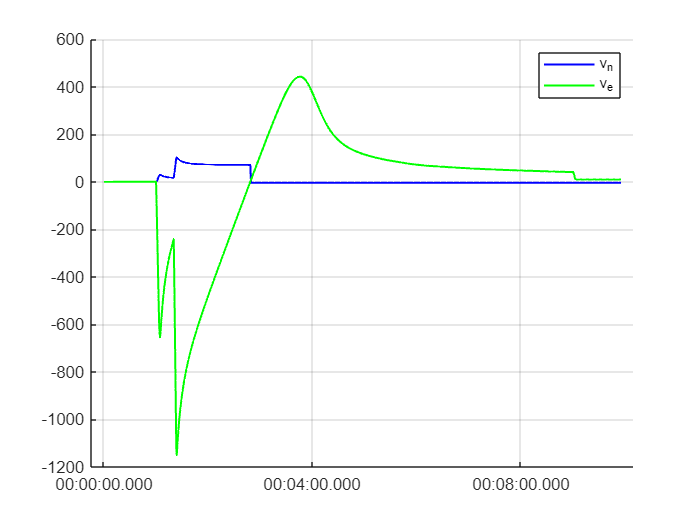

figure
hold on
plot(time,telemetry_RAS.gps_v_n./1000,'-b',LineWidth=1.2)
% plot(time,telemetry_RAS.gps_v_e./1000,'-r',LineWidth=1.2)
plot(time,telemetry_RAS.gps_v_d./1000,'-g',LineWidth=1.2)
% plot(time-time_adjust,telemetry_RAS.pd,'-k',LineWidth=1.2)
grid on 
legend('v_n', 'v_e', 'v_d')